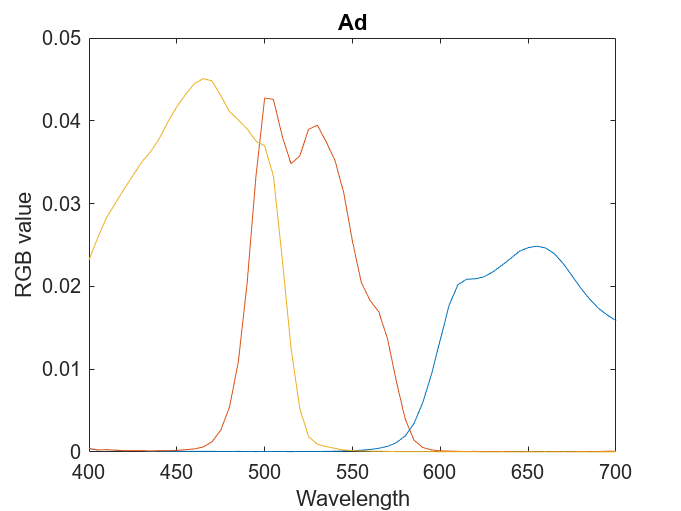

clear
clf

% 1.1
load("Ad.mat");
load("Ad2.mat");

wavelength = 400:5:700;

plot(wavelength, Ad);
title("Ad")
xlabel("Wavelength")
ylabel("RGB value")

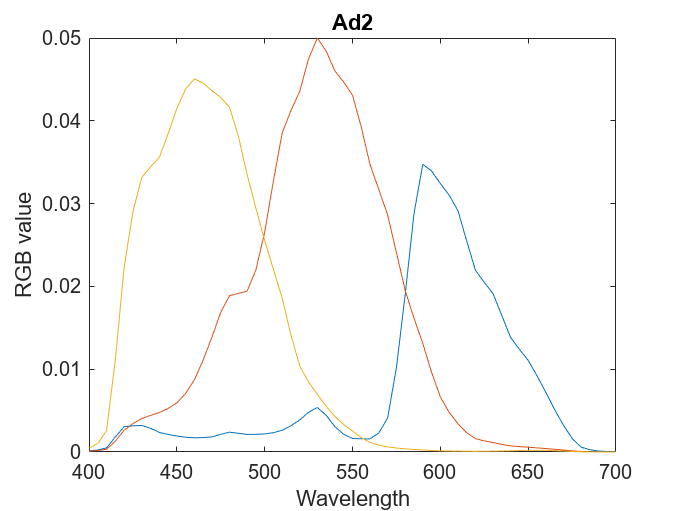


plot(wavelength, Ad2);
title("Ad2")
xlabel("Wavelength")
ylabel("RGB value")

**Answer:** No, it should not have the same output as the curves are different.

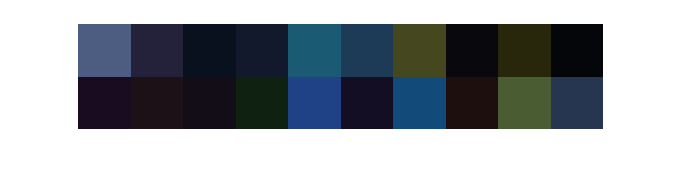

% 1.2
load("chips20.mat");
load("illum.mat");

RGB_raw_D65 = Ad' * (chips20 .* CIED65)';
showRGB(RGB_raw_D65')

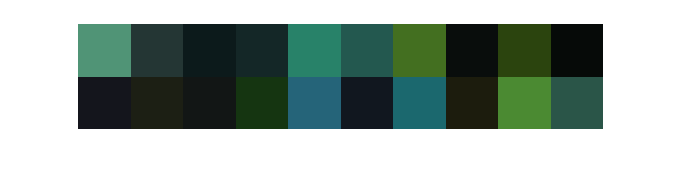


RGB_raw_D652 = Ad2' * (chips20 .* CIED65)';
showRGB(RGB_raw_D652')

**Answer:** The first camera is more "blue" and the second is more "green" which can be observed in the sensitivity functions.

% 2.1
e = ones(1,61);
k = Ad' * e';
k = 1./k

k =     2.1574
    1.7711
    1.1649


k2 = Ad2' * e';
k2 = 1./k2

k2 =     2.1161
    1.1433
    1.3476


**Answer:** We think it makes sense. All the RGB values get scaled up, but those with lower values have a higher factor to make them closer to the rest. The original images do not have much red, but the red values are scaled up more than the others.

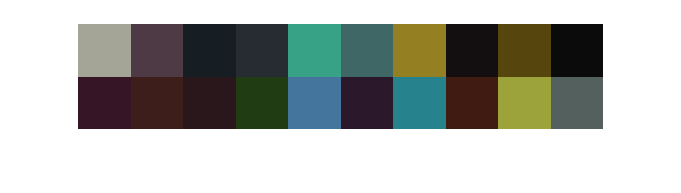

% 2.2
RGB_cal_D65 = RGB_raw_D65.*k;
RGB_cal_D652 = RGB_raw_D652.*k2;

showRGB(RGB_cal_D65')

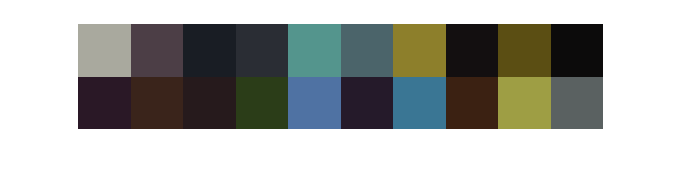

showRGB(RGB_cal_D652')

**Answer:** The results look a lot more stable with more varying colors.

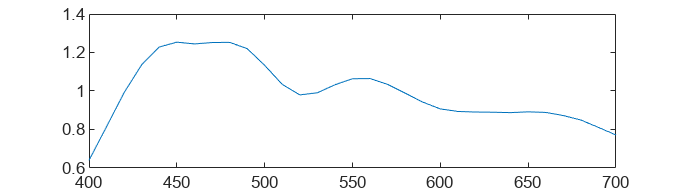

% 2.3
plot(wavelength, CIED65) % Outdoor

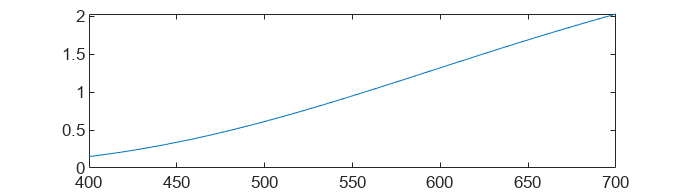

plot(wavelength, CIEA) % Indoor

**Answer:** Outdoor light is a lot more even with light of all wavelengths. (Should be colorless)

% 2.4
RGB_raw_A = Ad' * (chips20 .* CIED65)';
showRGB(RGB_raw_A')

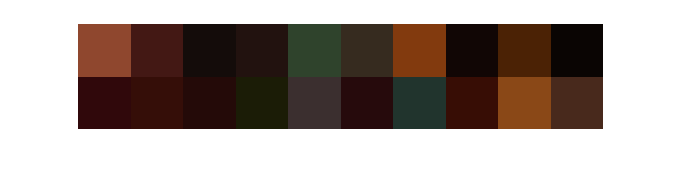


RGB_raw_A2 = Ad' * (chips20 .* CIEA)';
showRGB(RGB_raw_A2')

**Answer:** The light affects the color. CIEA is more of a "red light" and contributes to a higher R value.

% 2.5
% New calibration factors
R = ones(1,61);
k = Ad' * R';
k = 1./k

k =     2.1574
    1.7711
    1.1649


k2 = Ad2' * R';
k2 = 1./k2

k2 =     2.1161
    1.1433
    1.3476



% CIED65
RGB_cal_D65 = RGB_raw_D65.*k;
RGB_cal_D652 = RGB_raw_D652.*k2;

showRGB(RGB_cal_D65')

%showRGB(RGB_cal_D652')

% CIEA
RGB_cal_A = RGB_raw_A.*k;
RGB_cal_A2 = RGB_raw_A2.*k2;

showRGB(RGB_cal_A')

%showRGB(RGB_cal_A2')

**Answer:** They are identical and have a proper balance as they are adapted for the white point.

% 3.1
load("xyz.mat")

% Normalization factor
k = xyz(:, 2)' * CIED65';
k = 100./k

k = 4.6460


XYZ_D65_ref = xyz' * (chips20 .* CIED65)' * k'

XYZ_D65_ref =    66.5076   29.1415   10.3354   17.0944   37.2524   31.4696   51.8681    7.1516   35.7168    4.5704   14.7977   21.2515   13.6952   19.1563   34.5574   13.8335   26.8255   20.8937   59.1042   36.1553
   67.2653   25.9561   10.4588   16.8158   49.3000   35.3276   57.1830    6.4429   38.2742    4.5382   10.4425   18.0936   11.4180   25.1057   36.1143   10.5687   34.9493   17.7770   67.6801   37.2942
   61.0087   28.3929   14.4753   20.9340   50.2915   40.5003   10.0020    6.4265    5.4609    4.4085   16.5167   10.6582   11.4388    7.5209   65.7332   18.0017   54.8397    6.5922   17.7720   37.8082



% 3.2
load("M_XYZ2RGB.mat")


XYZ_cal_D65 = inv(M_XYZ2RGB)*RGB_cal_D65;
e = computeDeltaE(XYZ_D65_ref, XYZ_cal_D65);
mean(e)

ans = 12.6418

max(e)

ans = 31.6232

**Answer:** There will be a noticable difference between RGB and LAB as the mean is about 12-13 "steps" in color difference for human perception. We perceive values under 1 as identical in this case.

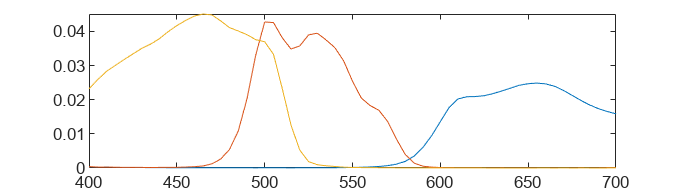

% 3.3
plot(wavelength, Ad)

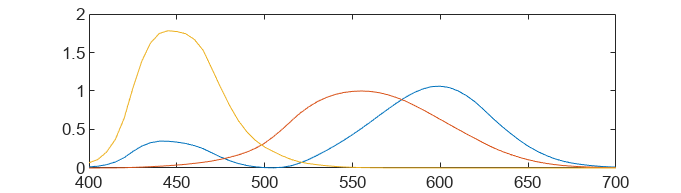

plot(wavelength, xyz)


% 3.4
A = pinv(RGB_cal_D65')*XYZ_D65_ref';
estimate = RGB_cal_D65'*A;
e = computeDeltaE(XYZ_D65_ref, estimate');
mean(e)

ans = 2.1977

max(e)

ans = 5.8376

**Answer:** Mean square error is better than the previous method.

% 3.5
A = Optimize_poly(RGB_cal_D65, XYZ_D65_ref);
estimate = Polynomial_regression(RGB_cal_D65, A);
e = computeDeltaE(XYZ_D65_ref, estimate);
mean(e)

ans = 1.0238

max(e)

ans = 3.1053

**Answer:** The first method (matrix) is pretty bad compared to the rest. The best is the third method (polynomial regression).